## **Introduction**

### Introduction of the given task

a

### Background Theory

### Problem Description 

(What we have to model and why)

## Methodology

### Mathematical/Computational Model

An article by Alexandridis A., et. al (2008) demonstrates a simple cellular automaton that can model wildfire spreading. Each cell is given one of four "state"s:

- The cell has no fuel, which can represent cities and rural areas with low vegetation.

- The cell contains fuel that has not been ignited.

- The cell contains fuel that is currently burning.

- The cell contained fuel that has burned.

These states are put into a matrix $\mathit{\mathbf{F}}$ and evolved using these rules:

- If the cell's state is 1 (no fuel), then it will not evolve, since we assume that cells with no fuel cannot burn.

- If the cell's state is 3 (burning), then it will evolve to state 4 (burned down) on the next time step.

- If the cell's state is 4 (burned down), then it will not evolve, since there is no more fuel left.

- If a cell's state is 3 (burning), each Moore neighbour will have a probability to evolving into cell state 3 with a probability $p_{\textrm{burn}}$.

The value of $p_{\textrm{burn}}$ is variable and will be discussed in the next subsection.

### MATLAB Implementation

Cell state was implemented as an enumeration class for code readability purposes.

*Code Example 1: CellState enumeration class as defined in CellState.m*

A state matrix can be initialised using MATLAB's inbuilt ones function and then casting every value. For example, to create a 10x10 matrix of unignited fuel with a burning cell in the centre, use the following:

state = CellState(2 * ones(10, 10)); % CellState.NotIgnited = 2
state(5, 5) = CellState.Burning      % Set the centre cell on fire

To evolve the automata, create a new function:

function next = evolve_sim(state, constant_burn_probability)
    [height, width] = size(state);
    next = CellState(zeros(height, width));

    % Rule 1: No fuel cells -> no fuel cells
    no_fuel_mask = state == CellState.NoFuel;
    next(no_fuel_mask) = CellState.NoFuel;
    
    % Rule 2: Burning cells -> burned down cells
    burning_mask = state == CellState.Burning;
    next(burning_mask) = CellState.BurnedDown;

    % Rule 3: Burned down cells -> burned down cells
    burned_down_mask = state == CellState.BurnedDown;
    next(burned_down_mask) = CellState.BurnedDown;

    % Rule 4: Burning cells can ignite non-ignited Moore neighbours with
    % probability p_burn.
    % At the moment, we'll assume a constant burn probability.
    burning_neighbour_mask = get_burning_neighbour_mask(state);
    burning_neighbour_mask = burning_neighbour_mask & state == CellState.NotIgnited;
    ignition_mask = burning_neighbour_mask & (rand(height, width) < constant_burn_probability);
    next(ignition_mask) = CellState.Burning;

    % All cells that weren't ignited this evolution stay not ignite.
    still_not_ignited_mask = state == CellState.NotIgnited & ~ignition_mask;
    next(still_not_ignited_mask) = CellState.NotIgnited;
end

There is a function that hasn't been defined here: get_burning_neighbour_mask. However, this can be easily implemented using the below function.

*Code Example 2: shift function as defined in shift.m*

As per the documentation, the shift function shifts a matrix in a direction and fills the empty space with 0s. Using this function, it becomes trivial to find the mask of the neighbours of the burning cells.

function mask = get_burning_neighbour_mask(state)
    centre = state == CellState.Burning;
    
    north = shift(centre, 1, 1);
    south = shift(centre, 1, 0);
    east = shift(centre, 1, 2);
    west = shift(centre, 1, 3);
    
    north_east = shift(north, 1, 2);
    north_west = shift(north, 1, 3);
    south_east = shift(south, 1, 2);
    south_west = shift(south, 1, 3);

    mask = north_west |  north | north_east | ...
                 east | centre |       west | ...
           south_west |  south | south_east;
end

state = evolve_sim(state, 0.75)

If you run the above code multiple times, you can view the cellular automata predict the path of a fire.

This is a very simplistic wildfire predictor, as it assumes every cell is equally likely to ignite, assumes there is no wind, and also assumes a perfectly flat surface. Account for each of these new parameters would involve having a function with a large signature, such as

which would be very unwieldy for anyone to use.

This is why for the purposes of this report, the code responsible for simulating a fire was put into a class, as it reduces the need for large function signatures such as the one above, and allows new parameters to be added while not breaking any existing code.

The WildfireSimulation class has the function to evolve the cellular automata and an extra function to plot the cell states on a figure. This simulation takes elevation, vegetation types and density, and probabilities for constant ignition and continued burning into account.

The below code shows a demonstration of an incomplete fire break.

% Create `CellState` matrix
initial_state = CellState(2 * ones(50, 50));          % CellState.NotIgnited = 2
initial_state(1, 1) = CellState.Burning;              % Set top left cell to be burning.
initial_state(25, [1:40, 42:50]) = CellState.NoFuel;  % Create simulated fire break.

% Create wildfire simulation and set parameters
sim = WildfireSimulation(initial_state);
sim.vegetation = -0.5 * ones(50, 50); % Vegetation matrix alters probability that a cell can be ignited.
sim.constant_ignition_probability = 0.75; 
sim.continued_burn_probability = 0.5; % The probability that a burning cell remains a burning cell on the next generation.

% Run simulation 100 steps and plot.
figure;
sim.plot()

for i = 1:100
    sim = sim.step(); % Progress the automata one generation
    sim.plot();

    drawnow;
end

The demo shows that the fire stops at the break, but as soon as the fire reaches the gap in the fire break, it quickly spreads out on the other half of the grid.

When running the simulation multiple times, you'll notice that the top half always completely burns. However, the fire can sometimes die out before it ignites the bottom half.

% Measure Burned Area
burned_mask = (sim.state == CellState.Burning) | (sim.state == CellState.BurnedDown);
cell_length = sim.units_per_cell;    
cell_area = cell_length^2;             

burned_cells = sum(burned_mask(:));
burned_area_m2 = burned_cells * cell_area;
burned_area_hectares = burned_area_m2 / 10000;

disp("Burned cells: " + burned_cells)
disp("Burned area: " + burned_area_m2 + " m^2")

Burned cells: 1918


disp("Burned area: " + burned_area_hectares + " hectares")

Burned area: 1918 m^2


figure

Burned area: 0.1918 hectares


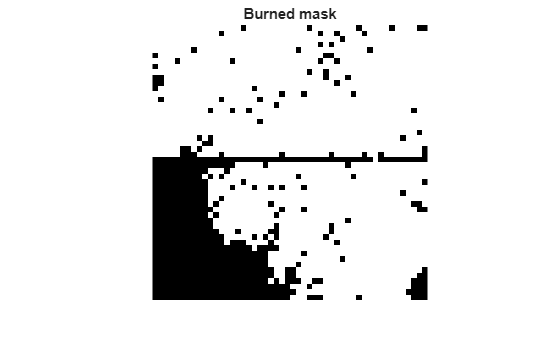

imshow(burned_mask, 'InitialMagnification', 'fit')
title('Burned mask')

#### Differences between example automata and the WildfireSimulation class

There are a lot of differences between the example automata developed at the start of the this section and our final implementation. Take the function that evolves the state matrix:

*Code Example 3: WildfireSimulation.step() source code.*

The most notable differences between the example and the final implementation are that cells that are burning do not always evolve to the "burned down" state on the next generation and that each cell has a specific ignition probability, as opposed to the constant probability. This is encoded using an *ignition probability matrix*.

## Conclusion

### Results

### Discussion 

(Reply to given task and suggest ways of fire prevention)

### Limitations 

(In modelling and code)

### Potential Improvements

## Bibliography

Alexandridis, A., Vakalis, D., Siettos, C.I., Bafas, G.V (2008). *A cellular automata model for forest fire spread prediction: The case of the wildfire that swept through Spetses Island in 1990* [article]. Applied Mathematics and Computation. Available at: [https://www.sciencedirect.com/science/article/abs/pii/S0096300308004943](https://www.sciencedirect.com/science/article/abs/pii/S0096300308004943)

Li, Xiaochi, (2018). *Wildfire simulation using paralleled cellular automaton *[online].GitHub. Available at: [https://github.com/XC-Li/Parallel_CellularAutomaton_Wildfire/blob/master/Wild_Fire.py](https://github.com/XC-Li/Parallel_CellularAutomaton_Wildfire/blob/master/Wild_Fire.py)